# Ex10. Introduction to Signals and systems

### s1320112/ Motohisa YAMANO

## 1. Plot Windows for LPF

This assignment focuses on designing FIR filters using the windowing method. We compare four types of windows—Rectangular, Hann, Hamming, and Blackman—to approximate the impulse response of an ideal Low-Pass Filter (LPF). Following the provided sample code, the parameters are set to M = 10 (filter order related) and L = 50 (time length). The results are organized into a 5x3 subplot grid to facilitate a comparative analysis of their characteristics.

#### 1.1. MATLAB Code

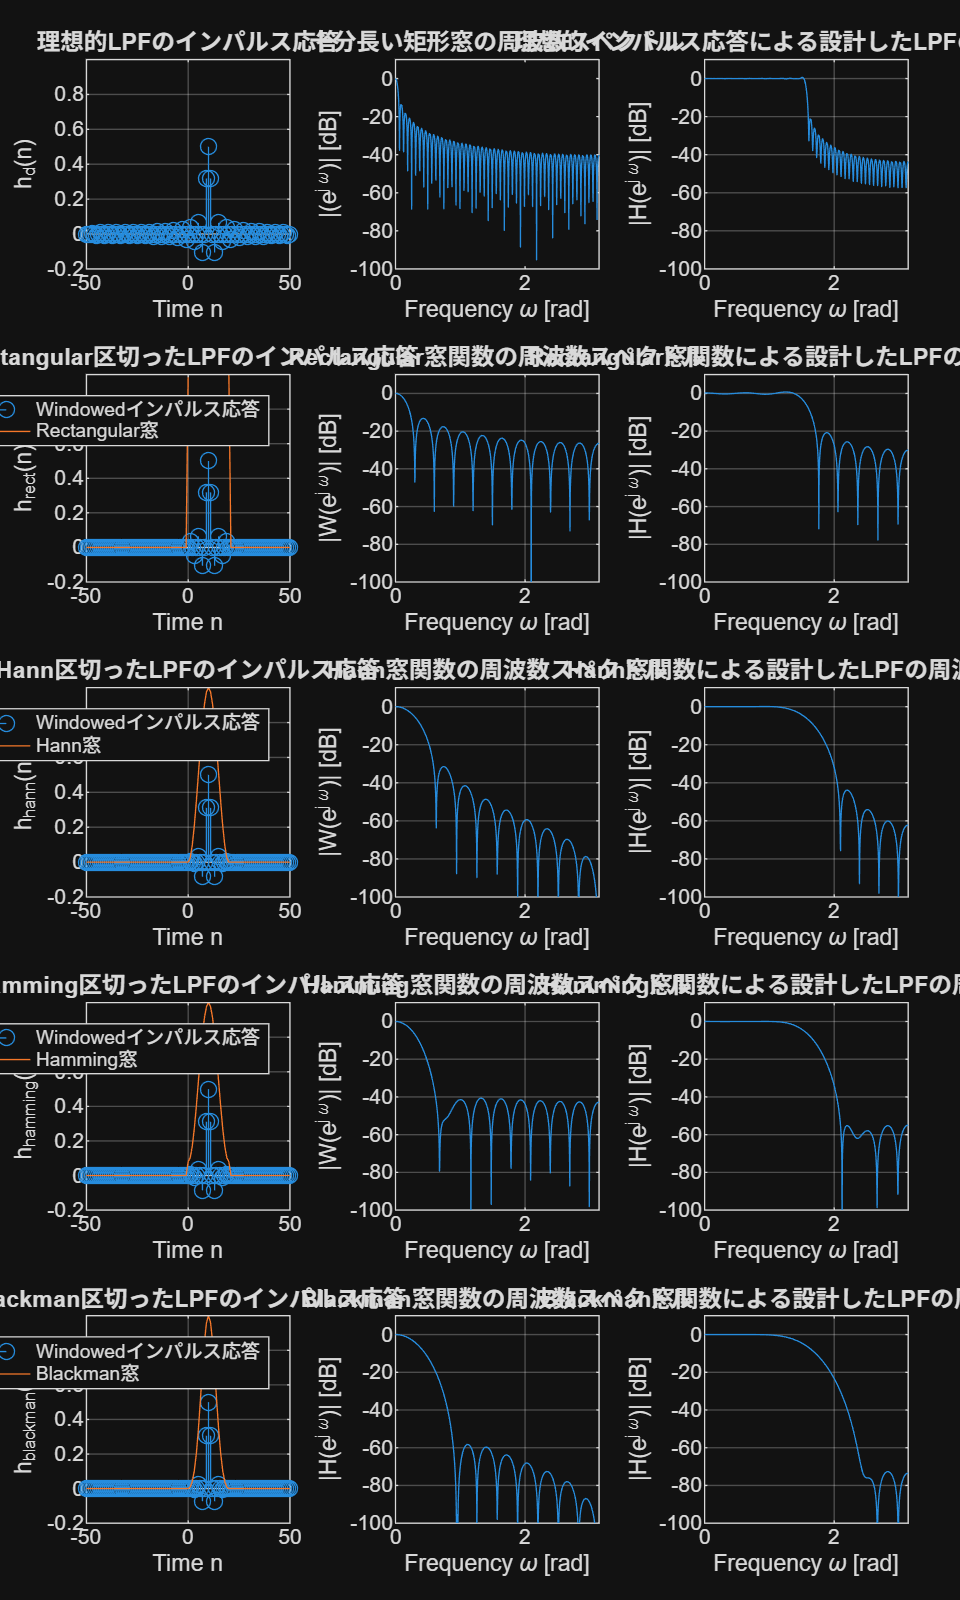

clf;
clear;
L = 50;
n = -L:L;
M = 10;
N = 2*M+1;
w = linspace(0,pi,1024);
wc = 0.5*pi;

figure('Position', [100 100 1200 2000]);
t = tiledlayout(5, 3, 'Padding', 'compact', 'TileSpacing', 'compact');

hd = (wc/pi) * sinc((n-M)*wc/pi);
nexttile;
stem(n, hd);
axis([-L L -0.2 1]);
grid on;
xlabel('Time n');
ylabel('h_d(n)');
title('理想的LPFのインパルス応答');

win = rectwin(2*L + 1);
Win = freqz(win, 1, w);
maxWin = max(abs(Win));
nexttile;
plot(w, 20*log10(abs(Win)/maxWin));
axis([0 pi -100 10]);
xlabel('Frequency \omega [rad]');
ylabel('|(e^{j \omega})| [dB]');
title('十分長い矩形窓の周波数スペクトル');

H = freqz(hd, 1, w);
nexttile;
plot(w, 20 * log10(abs(H)));
axis([0 pi -100 10]);
grid on;
xlabel('Frequency \omega [rad]');
ylabel('|H(e^{j \omega})| [dB]');
title('理想的インパルス応答による設計したLPFの周波数応答');

win = rectwin(N);
winz = [zeros(1, L-M) win' zeros(1, L-M)];
winz = wshift('1D', winz, -M);
h = hd .* winz;
nexttile;
stem(n,h);
hold on;
plot(n, winz);
axis([-L L -0.2 1]);
grid on;
xlabel('Time n');
ylabel('h_r_e_c_t(n)');
title('Rectangular区切ったLPFのインパルス応答');
legend('Windowedインパルス応答','Rectangular窓','Location','northeast');

Win = freqz(win, 1, w);
maxWin = max(abs(Win));
nexttile;
plot(w, 20*log10(abs(Win)/maxWin));
axis([0 pi -100 10]);
grid on;
xlabel('Frequency \omega [rad]');
ylabel('|W(e^{j \omega})| [dB]');
title('Rectangular窓関数の周波数スペクトル');

H = freqz(h, 1,w);
nexttile;
plot(w, 20*log10(abs(H)));
axis([0 pi -100 10]);
grid on;
xlabel('Frequency \omega [rad]');
ylabel('|H(e^{j \omega})| [dB]');
title('Rectangular窓関数による設計したLPFの周波数応答');

%%------Hann-----

win = hann(N);
winz = [zeros(1, L-M) win' zeros(1, L-M)];
winz = wshift('1D', winz, -M);
h = hd .* winz;
nexttile;
stem(n,h);
hold on;
plot(n, winz);
axis([-L L -0.2 1]);
grid on;
xlabel('Time n');
ylabel('h_h_a_n_n(n)');
title('Hann区切ったLPFのインパルス応答');
legend('Windowedインパルス応答','Hann窓','Location','northeast');

Win = freqz(win, 1, w);
maxWin = max(abs(Win));
nexttile;
plot(w, 20*log10(abs(Win)/maxWin));
axis([0 pi -100 10]);
grid on;
xlabel('Frequency \omega [rad]');
ylabel('|W(e^{j \omega})| [dB]');
title('Hann窓関数の周波数スペクトル');

H = freqz(h, 1,w);
nexttile;
plot(w, 20*log10(abs(H)));
axis([0 pi -100 10]);
grid on;
xlabel('Frequency \omega [rad]');
ylabel('|H(e^{j \omega})| [dB]');
title('Hann窓関数による設計したLPFの周波数応答');

%%------Hamming-----

win = hamming(N);
winz = [zeros(1, L-M) win' zeros(1, L-M)];
winz = wshift('1D', winz, -M);
h = hd .* winz;
nexttile;
stem(n,h);
hold on;
plot(n, winz);
axis([-L L -0.2 1]);
grid on;
xlabel('Time n');
ylabel('h_h_a_m_m_i_n_g(n)');
title('Hamming区切ったLPFのインパルス応答');
legend('Windowedインパルス応答','Hamming窓','Location','northeast');

Win = freqz(win, 1, w);
maxWin = max(abs(Win));
nexttile;
plot(w, 20*log10(abs(Win)/maxWin));
axis([0 pi -100 10]);
grid on;
xlabel('Frequency \omega [rad]');
ylabel('|W(e^{j \omega})| [dB]');
title('Hamming窓関数の周波数スペクトル');

H = freqz(h, 1,w);
nexttile;
plot(w, 20*log10(abs(H)));
axis([0 pi -100 10]);
grid on;
xlabel('Frequency \omega [rad]');
ylabel('|H(e^{j \omega})| [dB]');
title('Hamming窓関数による設計したLPFの周波数応答');

%%------Blackman-----

win = blackman(N);
winz = [zeros(1, L-M) win' zeros(1, L-M)];
winz = wshift('1D', winz, -M);
h = hd .* winz;
nexttile;
stem(n,h);
hold on;
plot(n, winz);
axis([-L L -0.2 1]);
grid on;
xlabel('Time n');
ylabel('h_b_l_a_c_k_m_a_n(n)');
title('Blackman区切ったLPFのインパルス応答');
legend('Windowedインパルス応答','Blackman窓','Location','northeast');

Win = freqz(win, 1, w);
maxWin = max(abs(Win));
nexttile;
plot(w, 20*log10(abs(Win)/maxWin));
axis([0 pi -100 10]);
grid on;
xlabel('Frequency \omega [rad]');
ylabel('|H(e^{j \omega})| [dB]');
title('Blackman窓関数の周波数スペクトル');

H = freqz(h, 1,w);
nexttile;
plot(w, 20*log10(abs(H)));
axis([0 pi -100 10]);
grid on;
xlabel('Frequency \omega [rad]');
ylabel('|H(e^{j \omega})| [dB]');
title('Blackman窓関数による設計したLPFの周波数応答');

#### 1.2. Discussion

The characteristics of the FIR filters designed with different windows show a clear **trade-off** between the **transition band width** and the **stopband attenuation**.

- Transition Band:The Rectangular window provides the narrowest (sharpest) transition band, as seen in the frequency response where the magnitude drops most abruptly at the cutoff frequency ω_c = 0.5*pi. In contrast, the Blackman window results in the widest (gentlest) transition band, with Hann and Hamming windows falling in between.

- Passband and Stopband Ripples:While the Rectangular window is sharp, it suffers from significant ripples (side-lobes) in both the passband and stopband due to the Gibbs phenomenon. These ripples indicate that high-frequency signals are not effectively blocked, with stopband attenuation limited to approximately -21 dB.

- Comparison of Performance:As we move from Rectangular to Hann, Hamming, and finally Blackman, the ripples gradually decrease. The Blackman window achieves the highest stopband attenuation (plummeting well below -60 dB), making it the most effective for suppressing unwanted high-frequency components, despite its wider transition band.

## 2. Math Problem

Below is the snapshot of my answer in fill-blank math problem.